１：全モデルでの平均音速値をプロットする．ここで構造の影響が大きく出ているデータを目視で特定する．

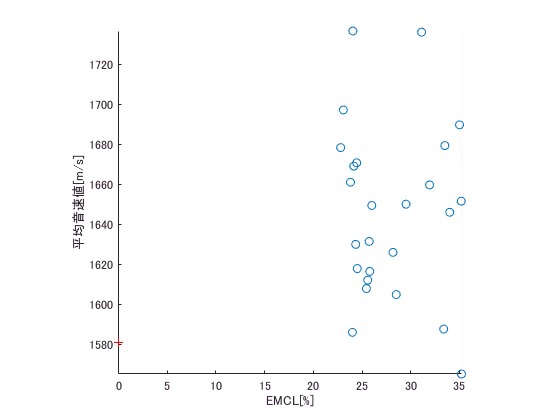

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel\2018_08_12_failure')
load('2018_08_05_aveSOS&steSOS_1-25')
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\medium\2018_08_10_realisticScatter')
load('rate_EMCLs')
[~, num_pattern] = size(aveSOS);
v_muscle = 1580;
v_fat = 1450;
figure;
hold on
scatter(rate_EMCLs(1,:), aveSOS(1,:));
% plot(,v_muscle*(1-x1/100)+v_fat*x1/100,'--');
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_08_no_object')
load('2018_08_08_aveSOS&steSOS')
scatter(0,aveSOS,'r+');
xlabel('EMCL[%]');
ylabel('平均音速値[m/s]')
axis square
axis tight
hold off

結果がぐちゃぐちゃになってしまった．何かがおかしい．

２：１はtof-map作成の時点で失敗している．

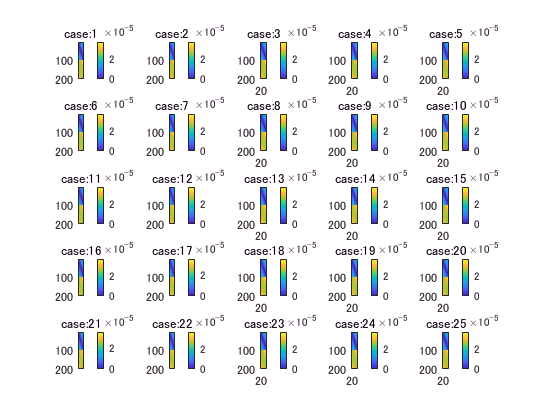

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel\2018_08_12_failure')
load('2018_08_05_aveSOS&steSOS_1-25')
figure;
for i = 1:25
    subplot(5,5,i);
    imagesc(tof_cell(:,:,i));
    colorbar
    myfilename = sprintf('case:%d',i);
    title(myfilename);
end

３：tof-pickerを設定し直す．

%まずはtofデータ一個を取り出して考える．
% cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_08_no_object')
% load('NoObject')
% tof_data_r0 = tof_data;
% [tof_x, tof_y] = size(tof_data_r0);
addpath(genpath('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\codes'))
%RFデータを読みこむ
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_05_no_object\NoObject')
load('rfdata.mat')
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_05_no_object\NoObject');
load('kgrid')
rfdata_no_object = rfdata;

tof_map = threshold_picker(rfdata_no_object,kgrid);
v_cal_no_object = 40e-03/tof_map(150,50)

v_cal_no_object = 1.5804e+03

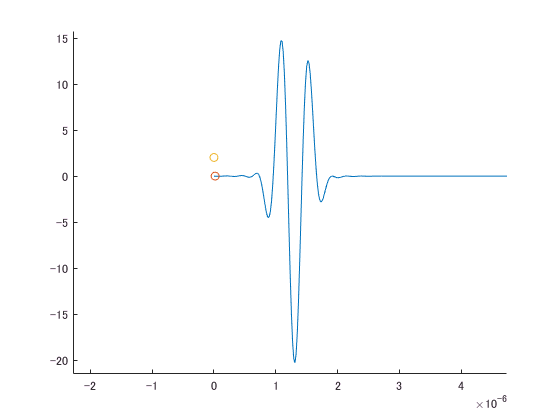

figure;
hold on
plot(kgrid.t_array(1,:),rfdata_no_object(:,50,50));
xlim([-0.00000228 0.00000474])
ylim([-21.52 15.78])
scatter(tof_map(50,50),0);
scatter(0,threshold_map(50,50));

４：rfdata（肉断面），特にtof-map生成に失敗した原因となった箇所のｒｆデータを見る．

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_12_realisticScatter')
cd('case1')
load('rfdata.mat')
load('kgrid.mat')

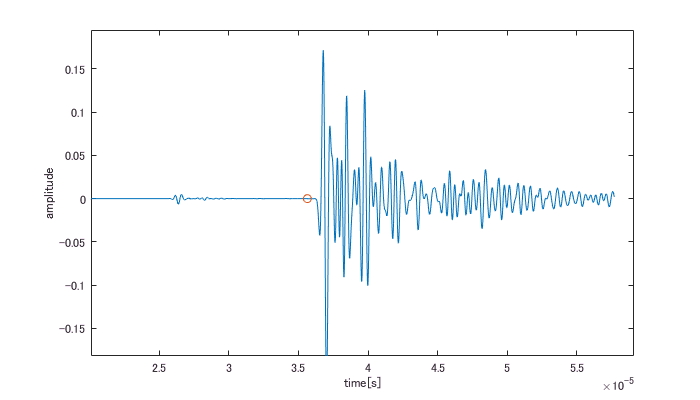

figure;
plot(kgrid.t_array(1,:),rfdata(:,200,5))
hold on
tof_map = threshold_picker(rfdata,kgrid);
scatter(tof_map(200,5),0);
xlabel('time[s]')
ylabel('amplitude')
xlim([0.0000201 0.0000591])
ylim([-0.182 0.195])
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel\rfdata_tr_5_re_200','png',[700,400]);

初期微動のようなものが最初に来ている．これを誤って拾ってしまったのだろう．

５：再度tof-mapを表示してみる．（k-wave\script参照）

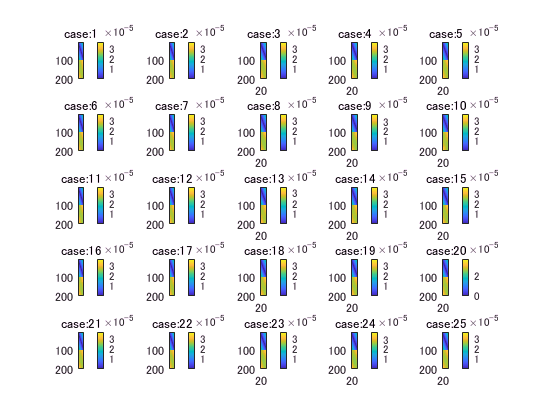

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel')
load('2018_08_12_aveSOS&steSOS_1-25')
figure;
for i = 1:25
    subplot(5,5,i);
    imagesc(tof_cell(:,:,i));
    colorbar
    myfilename = sprintf('case:%d',i);
    title(myfilename);
end

どうやらokみたいだ．

６：全モデルでの平均音速値をプロットする．再度．

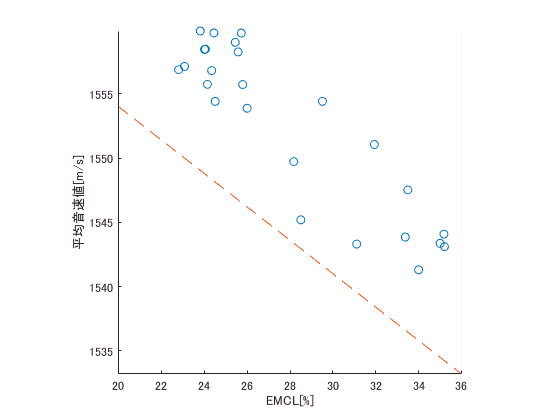

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel')
load('2018_08_12_aveSOS&steSOS_1-25')
load('rate_EMCLs')
[~, num_pattern] = size(aveSOS);
v_muscle = 1580;
v_fat = 1450;
x1 = 20:36;
figure;
hold on
scatter(rate_EMCLs(1,:), aveSOS(1,:));
plot(x1,v_muscle*(1-x1/100)+v_fat*x1/100,'--');
% cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_08_no_object')
% load('2018_08_08_aveSOS&steSOS')
% scatter(0,aveSOS,'r+');
xlabel('EMCL[%]');
ylabel('平均音速値[m/s]')
axis square
axis tight
hold off

かなり誤差が大きい．これでは正確に判定することは難しいだろう．

７：対向する素子ペアの距離（一定）と所要時間を用いた平均距離を用いて比較してみる．

addpath(genpath('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\codes'))
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\param')
load('param_2board.mat')
kgrid= makeGrid(param.grid.Nx, param.grid.dx, param.grid.Ny, param.grid.dy);

         Update codes to use the syntax kgrid = kWaveGrid(...).


tof_cell  = zeros(200,100,25);%{Receiver, Transmitter, ERate, Num, }
aveSOS2 = zeros(1,25);%{ERate, Num}
steSOS2_0 = zeros(100,25);
steSOS2 = zeros(1,25);
leng = zeros(1,100);
t_size = 40.e-3;
t_num = 200;%トランスデューサ数
t_pos = zeros(2, t_num);%センサ位置
t_pos(1,1:t_num/2) = -t_size/2:t_size/(t_num/2-1):t_size/2 ;%素子水平方向距離[m]
t_pos(2,1:t_num/2) = t_size/2;
t_pos(1,t_num/2+1:t_num) = t_pos(1,1:t_num/2);
t_pos(2,t_num/2+1:t_num) = -t_size/2;
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel');
myfilename = sprintf('2018_08_12_aveSOS&steSOS_1-25.mat');
load(myfilename);
for k = 1: t_num/2
    leng(1,k) = norm(t_pos(:,k)-t_pos(:,ind(1,k)));
end
for ii = 1:25
    for jj = 1:t_num/2
    aveSOS2(1,ii) = aveSOS2(1,ii) + leng(1,jj)/tof_cell(jj+100,jj,ii);
    steSOS2_0(jj,ii) = leng(1,jj)/tof_cell(jj+100,jj,ii);
    end
    aveSOS2(1,ii) = aveSOS2(1,ii)/(t_num/2);
    steSOS2(1,ii) = std(steSOS2_0(:,ii))/sqrt(t_num/2);
end

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel');
myfilename = sprintf('2018_08_12_aveSOS&steSOS_1-25');
save(myfilename,'aveSOS','steSOS','aveSOS2','steSOS2','tof_cell');

８：７で定義した平均音速も含めて全モデルでの平均音速値をプロットする．再度．

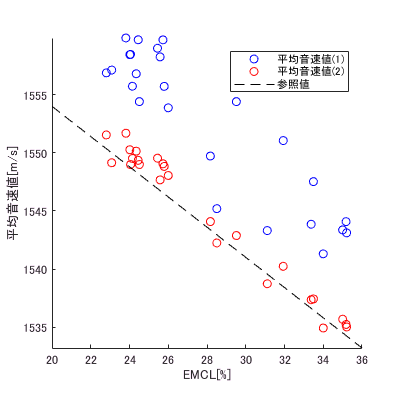

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel')
load('2018_08_12_aveSOS&steSOS_1-25')
load('rate_EMCLs')
[~, num_pattern] = size(aveSOS);
v_muscle = 1580;
v_fat = 1450;
x1 = 20:36;
figure;
hold on
scatter(rate_EMCLs(1,:), aveSOS(1,:),'b');
scatter(rate_EMCLs(1,:), aveSOS2(1,:),'r');
plot(x1,v_muscle*(1-x1/100)+v_fat*x1/100,'k--');
% cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_08_no_object')
% load('2018_08_08_aveSOS&steSOS')
% scatter(0,aveSOS,'r+');
xlabel('EMCL[%]');
ylabel('平均音速値[m/s]')
legend('平均音速値(1)','平均音速値(2)','参照値')
axis square
axis tight
hold off
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel\EMCL-aveSOS2','png',[400,400]);

９：最速経路をとる素子ペアの関係

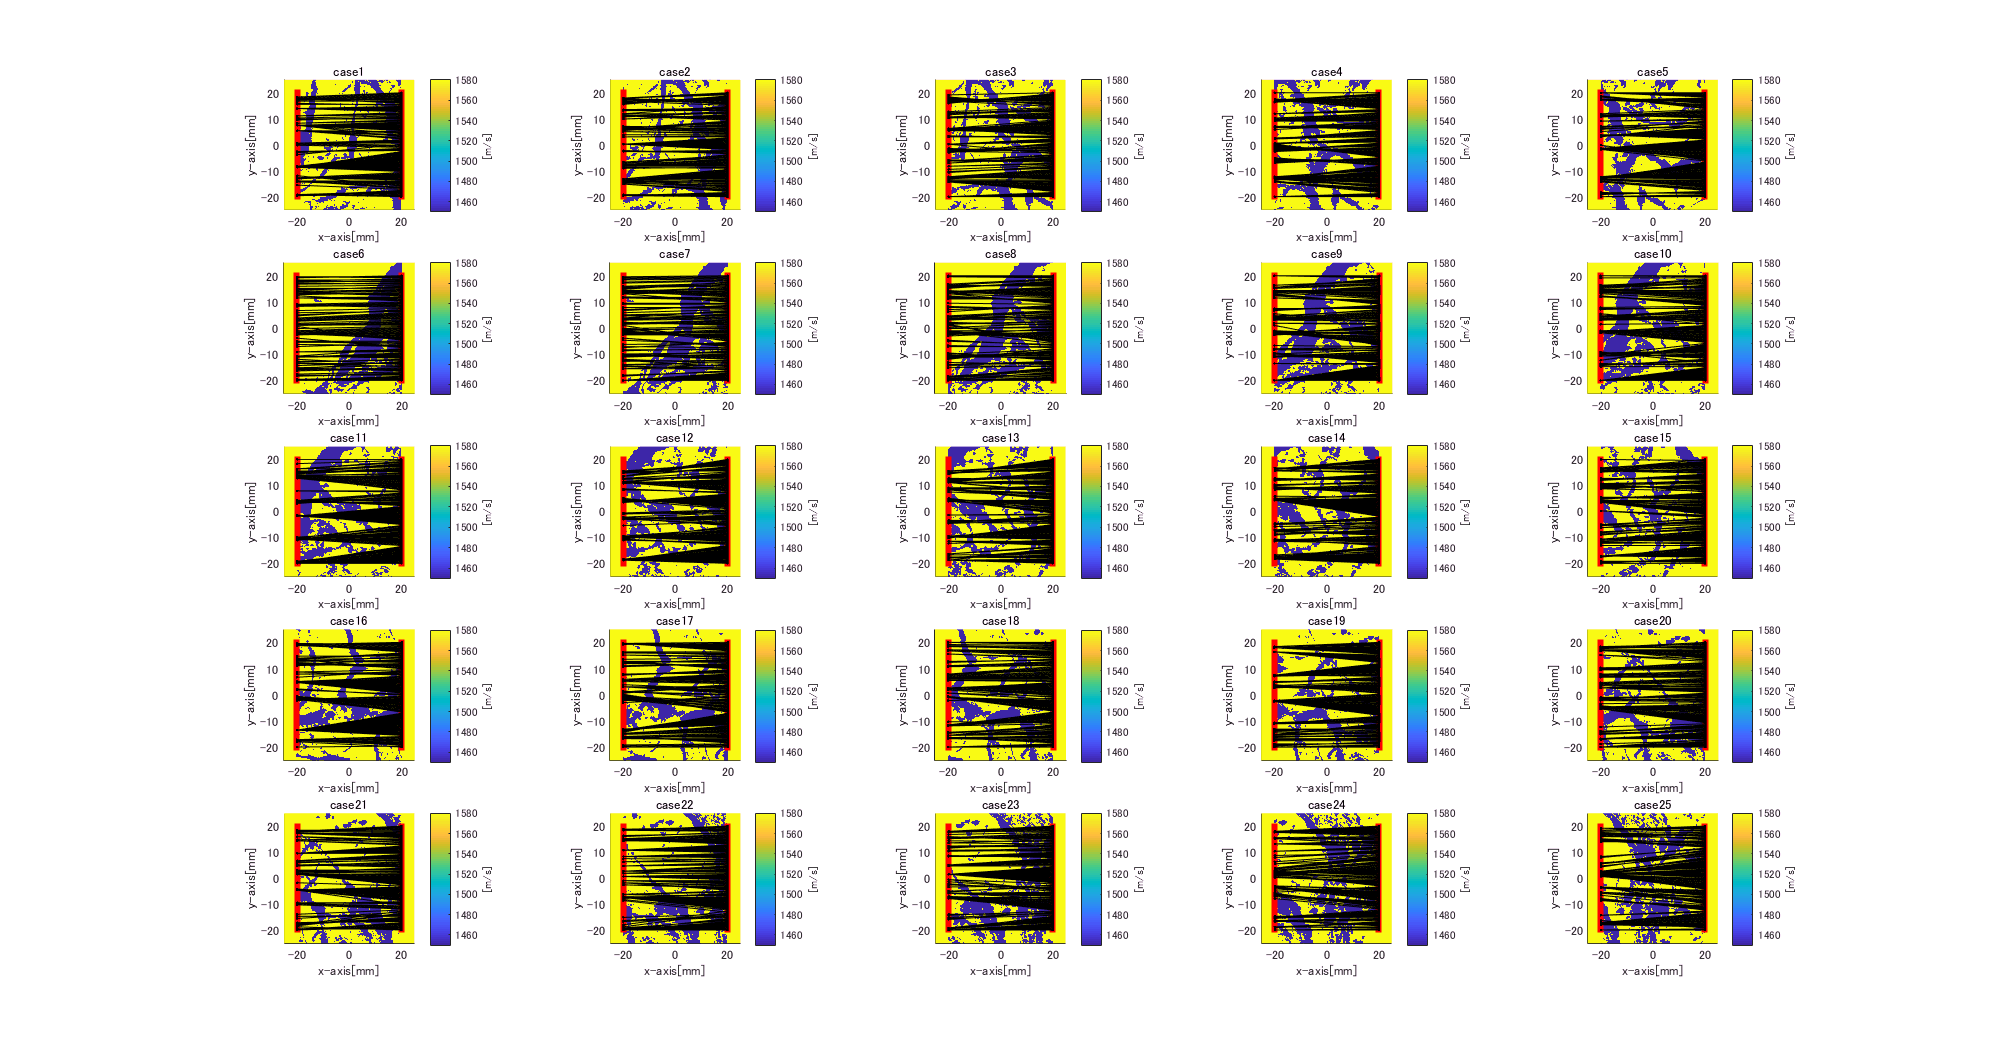

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\medium\2018_08_10_realisticScatter')
t_size = 40.e-3;
t_num = 200;%トランスデューサ数
t_pos = zeros(2, t_num);%センサ位置
t_pos(1,1:t_num/2) = -t_size/2:t_size/(t_num/2-1):t_size/2 ;%素子水平方向距離[m]
t_pos(2,1:t_num/2) = t_size/2;
t_pos(1,t_num/2+1:t_num) = t_pos(1,1:t_num/2);
t_pos(2,t_num/2+1:t_num) = -t_size/2;
figure;
for i = 1:25
    myfilename = sprintf('case%d',i);
    load(myfilename)
    subplot(5,5,i);
    hold on;
    imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,medium.sound_speed);
    axis equal
    axis tight
    scatter(t_pos(2,:)*1000,t_pos(1,:)*1000,'rs','filled');
    [~,ind] = min(tof_cell(101:end,:,i));
    ind = ind+100;
    for j = 1:length(ind)
        plot([t_pos(2,j)*1000;t_pos(2,ind(j))*1000],[t_pos(1,j)*1000;t_pos(1,ind(j))*1000],'.-k','LineWidth',0.01);
    end
    xlabel('x-axis[mm]')
    ylabel('y-axis[mm]')
    title(myfilename);
    colorbar;
    caxis([1450 1580]);
    c = colorbar;
    c.Label.String = '[m/s]';
    hold off;
end
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel\fastest_path_plot','png',[2000,2000]);